% Sierpinskin Gasket 谢尔宾斯基三角形使用了函数一次循环内多次自身递归
% 谢尔宾斯基三角形的绘制方法是将一个正方形分割成四个象限
% 左下象限留空，其余三个象限各自进一步分割成四个象限
% 进一步细分的左下象限也留空，其余三个象限继续分割，直至最后分割到正方形的边长为设定的单位长度
% 当正方形不能被进一步分割的时候，将左下象限外的三个象限填充，完成绘图。

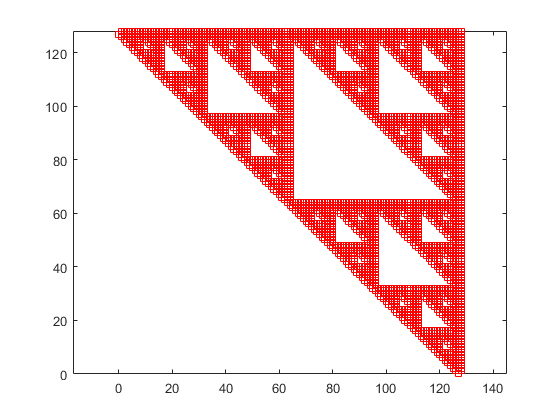

scale = 1;    % 最小分割单位
n = 7;     % 分割次数

lowerVertexX = 0;     % 待分割的正方形的左下顶点坐标
lowerVertexY = 0;     
upperVertexX = scale*2^n;    % 待分割的正方形的右上顶点坐标，正方形的边长（upperVertexX - lowerVertexX）为最小分割单位的 2^n 倍，因此可以进行 n 次 2 分。
upperVertexY = scale*2^n;

upperHalfDevideSquare(lowerVertexX, lowerVertexY, upperVertexX, upperVertexY, scale);

function upperHalfDevideSquare(lowerVertexX, lowerVertexY, upperVertexX, upperVertexY, scale)
    if (upperVertexX - lowerVertexX)/scale == 1    % 当正方形分割至边长为预设的最小分割单位时，不再继续分割，而是开始绘图。
        axis equal;
        plot([lowerVertexX, upperVertexX], [lowerVertexY, upperVertexY], 'rs');
        hold on;
    
    elseif (upperVertexX - lowerVertexX)/scale > 1
        lowerVertexX1 = lowerVertexX;    % 确定分割出的左上象限的正方形的左下顶点和右上顶点坐标
        lowerVertexY1 = (upperVertexY + lowerVertexY)/2;
        upperVertexX1 = (upperVertexX + lowerVertexX)/2;
        upperVertexY1 = upperVertexY;
        upperHalfDevideSquare(lowerVertexX1, lowerVertexY1, upperVertexX1, upperVertexY1, scale);    % 调用函数自身进一步分割左上象限的正方形
        
        lowerVertexX2 = (upperVertexX + lowerVertexX)/2;    % 确定分割出的右上象限的正方形的左下顶点和右上顶点坐标
        lowerVertexY2 = (upperVertexY + lowerVertexY)/2;
        upperVertexX2 = upperVertexX;
        upperVertexY2 = upperVertexY;
        upperHalfDevideSquare(lowerVertexX2, lowerVertexY2, upperVertexX2, upperVertexY2, scale);
        
        lowerVertexX3 = (upperVertexX + lowerVertexX)/2;    % 确定分割出的右下象限的正方形的左下顶点和右上顶点坐标
        lowerVertexY3 = lowerVertexY;
        upperVertexX3 = upperVertexX;
        upperVertexY3 = (upperVertexY + lowerVertexY)/2;
        upperHalfDevideSquare(lowerVertexX3, lowerVertexY3, upperVertexX3, upperVertexY3, scale);
    end    
end